**Semilog plot**. Over the past 5 years, the number of students in 6.094 has been 15, 25, 55, 115, 144. 

Class size seems like it’s growing exponentially. To verify this, plot these values on a plot with a log y scale and label it (**semilogy**, **xlabel**, **ylabel**, **title**). Use magenta square symbols of marker size 10 and line width 4, and no line connecting them. You may have to change the x limits to see all 5 symbols (**xlim**). If the relationship really is exponential, it will look linear on a log plot.

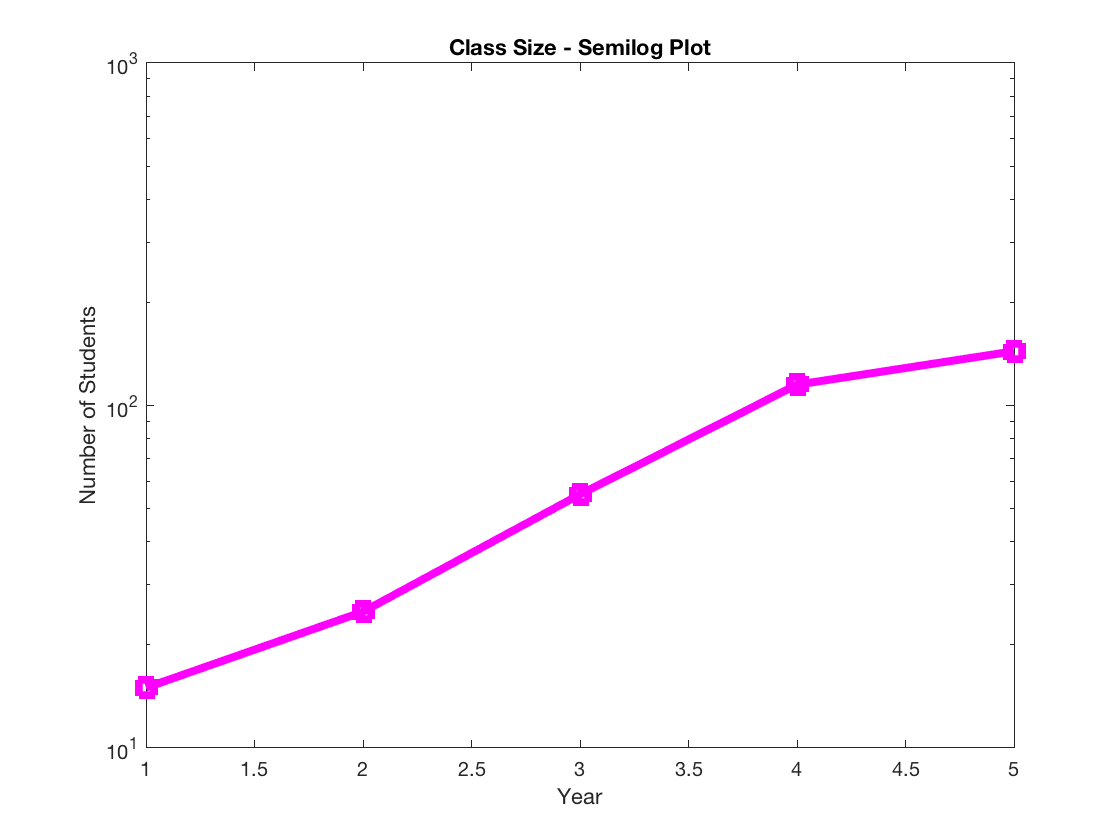

number_of_students = [15, 25, 55, 115, 144];
semilogy(number_of_students,'Color', 'm', 'Marker','square','LineWidth',4,'MarkerSize',10)
xlabel('Year')
ylabel('Number of Students')
title('Class Size - Semilog Plot')

**Bar graph**.  Make  a  vector  of  5  random  values  and  plot  them  on  a  bar  graph  using  red bars.

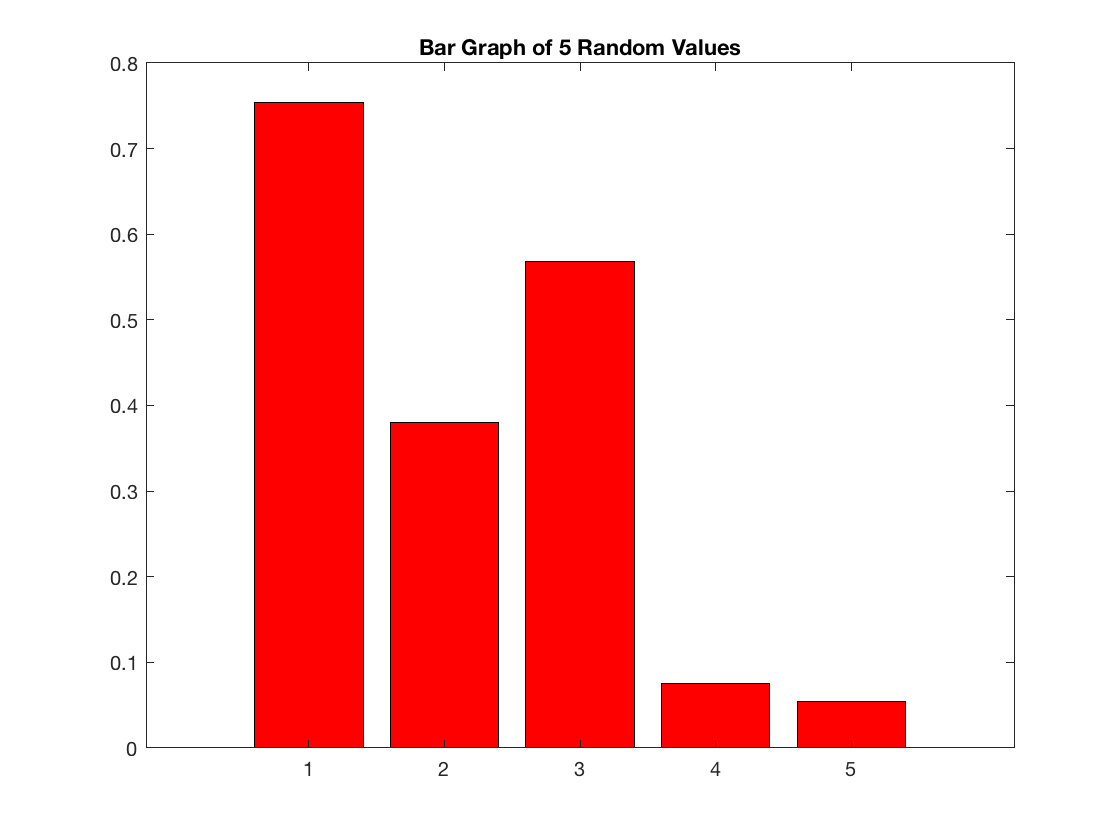

bar(rand(5,1),'grouped','red')
title('Bar Graph of 5 Random Values')

**Interpolation and surface plots. **The accompanying scrip 'randomSurface.m' defines the function generating the graph to the right.

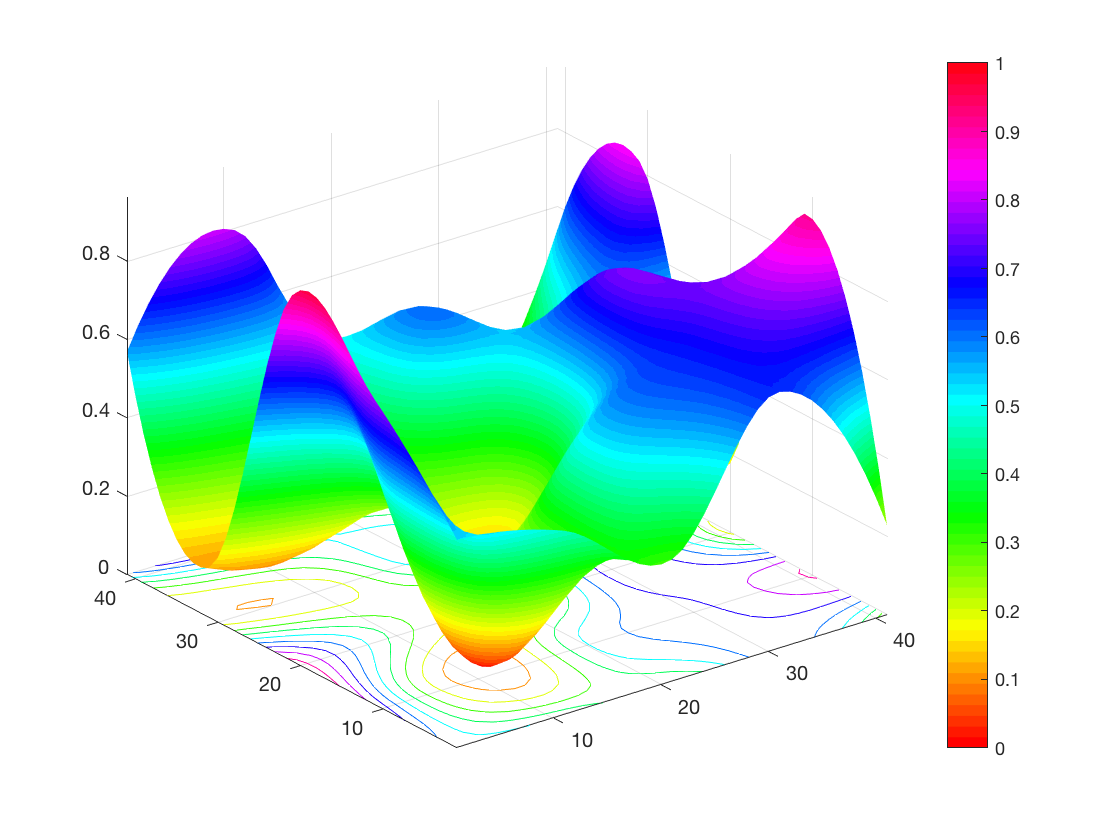

randomSurface

**Fun with find.** Write  a  function  to  return  the  index  of  the  value  that  is  nearest  to  a  desired value.  The  function  declaration  should  be: 

ind = findNearest(rand(2), 3)

ind = 1

x is a vector  or  matrix  of  values,  and `desiredVal `is the scalar value you want to find. Do not assume that `desiredVal `exists in `x`, rather find the value that is closest to `desiredVal`. If multiple values are the same distance from `desiredVal`, return all of their indices. Test your function to make sure it works on a few vectors and matrices. Useful functions are abs, min, and find. 

**Hint**: You may have some trouble using `min `when `x `is a matrix. To convert a matrix Q into a  vector  you  can  do  something  like 

y=Q(:)

y =    -0.5267
   -0.6483
   -0.1692
   -0.4147


Then, doing

m=min(y)

m = -0.6483

will give you the minimum value in `Q`. To find where this minimum occurs in `Q`, do 

inds=find(Q==m);

ind = 1

**Loops and flow control**. Make function called `loopTest(N) `that loops through the values 1 through N and for each number n it should display ‘n is divisible by 2’, ‘n is divisible by 3’, ‘n is divisible by 2 AND 3’ or ‘n is NOT divisible by 2 or 3’. Use a **for** loop, the function **mod** or **rem** to figure out if a number is divisible by 2 or 3, and **num2str** to convert each number to a string for displaying. You can use any combination of **if**, **else**, and **elseif**. 

loopTest(1:36)

1 is NOT divisible by 2 OR 3
2 is divisible by 2
3 is divisible by 3
4 is divisible by 2
5 is NOT divisible by 2 OR 3
6 is divisible by 2 AND 3
7 is NOT divisible by 2 OR 3
8 is divisible by 2
9 is divisible by 3
10 is divisible by 2
11 is NOT divisible by 2 OR 3
12 is divisible by 2 AND 3
13 is NOT divisible by 2 OR 3
14 is divisible by 2
15 is divisible by 3
16 is divisible by 2
17 is NOT divisible by 2 OR 3
18 is divisible by 2 AND 3
19 is NOT divisible by 2 OR 3
20 is divisible by 2
21 is divisible by 3
22 is divisible by 2
23 is NOT divisible by 2 OR 3
24 is divisible by 2 AND 3
25 is NOT divisible by 2 OR 3
26 is divisible by 2
27 is divisible by 3
28 is divisible by 2
29 is NOT divisible by 2 OR 3
30 is divisible by 2 AND 3
31 is NOT divisible by 2 OR 3
32 is divisible by 2
33 is divisible by 3
34 is divisible by 2
35 is NOT divisible by 2 OR 3
36 is divisible by 2 AND 3


function inds = findNearest(x, desiredVal)
    Q = abs(x - desiredVal);
    y = Q(:);
    m = min(y);
    inds = find(Q==m);
end

function loopTest(N)
    for idx = N
        if mod(N(idx), 6) == 0
            disp([num2str(N(idx)) ' is divisible by 2 AND 3'])
        elseif mod(N(idx), 3) == 0
            disp([num2str(N(idx)) ' is divisible by 3'])
        elseif mod(N(idx), 2) == 0
            disp([num2str(N(idx)) ' is divisible by 2'])
        else
            disp([num2str(N(idx)) ' is NOT divisible by 2 OR 3'])
        end
    end
end